% Before trying to construct hybrid images, it is suggested that you
% implement my_imfilter.m and then debug it using proj1_test_filtering.m

% Debugging tip: You can split your MATLAB code into cells using "%%"
% comments. The cell containing the cursor has a light yellow background,
% and you can press Ctrl+Enter to run just the code in that cell. This is
% useful when projects get more complex and slow to rerun from scratch

close all; % closes all figures

## Setup

read images and convert to floating point format

image2 = im2single(imread('../data/plane.bmp'));
image1 = im2single(imread('../data/bird.bmp'));

% Several additional test cases are provided for you, but feel free to make
% your own (you'll need to align the images in a photo editor such as
% Photoshop). The hybrid images will differ depending on which image you
% assign as image1 (which will provide the low frequencies) and which image
% you asign as image2 (which will provide the high frequencies)

## Filtering and Hybrid Image construction

cutoff_frequency = 8; %This is the standard deviation, in pixels, of the 
% Gaussian blur that will remove the high frequencies from one image and 
% remove the low frequencies from another image (by subtracting a blurred
% version from the original version). You will want to tune this for every
% image pair to get the best results.
filter = fspecial('Gaussian', cutoff_frequency*4+1, cutoff_frequency);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% YOUR CODE BELOW. Use my_imfilter to create 'low_frequencies' and
% 'high_frequencies' and then combine them to create 'hybrid_image'
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Remove the high frequencies from image1 by blurring it. The amount of
% blur that works best will vary with different image pairs
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

low_frequencies = my_imfilter(image1, filter);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Remove the low frequencies from image2. The easiest way to do this is to
% subtract a blurred version of image2 from the original version of image2.
% This will give you an image centered at zero with negative values.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

high_frequencies = image2 - my_imfilter(image2, filter);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Combine the high frequencies and low frequencies
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

hybrid_image = high_frequencies + low_frequencies;

## Visualize and save outputs

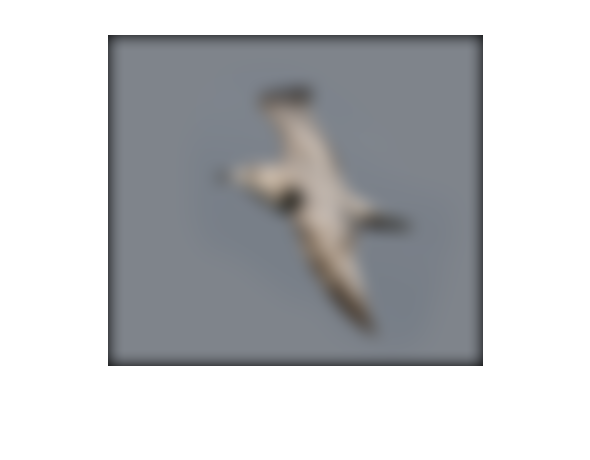

figure(1); imshow(low_frequencies)

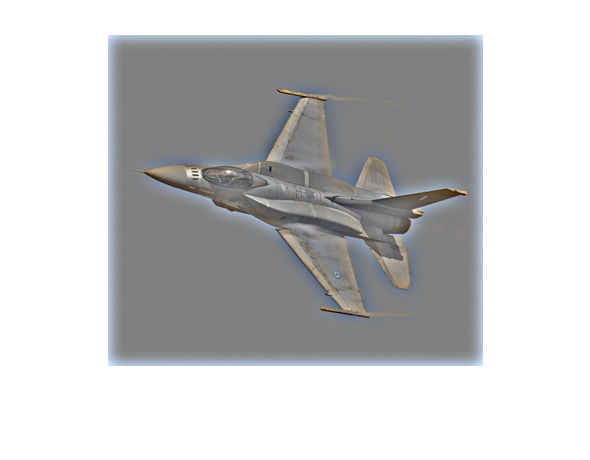

figure(2); imshow(high_frequencies + 0.5);

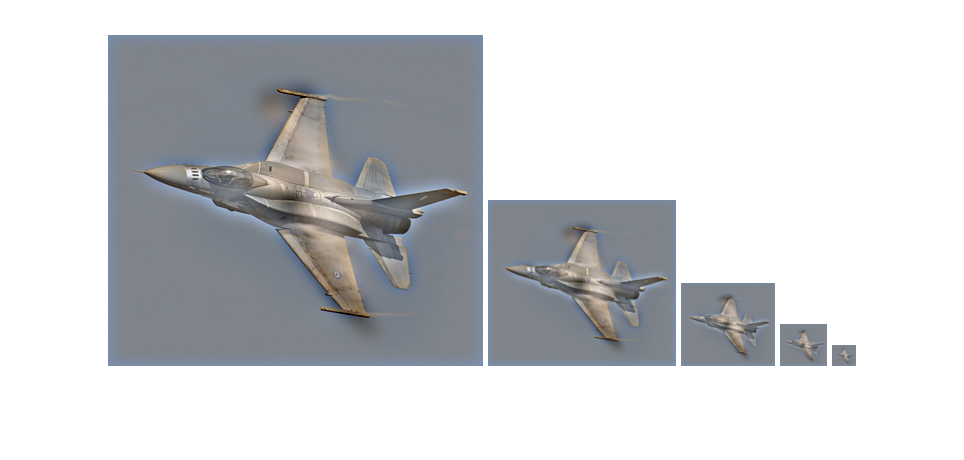

vis = vis_hybrid_image(hybrid_image);
figure(3); imshow(vis);

imwrite(low_frequencies, 'low_frequencies.jpg', 'quality', 95);
imwrite(high_frequencies + 0.5, 'high_frequencies.jpg', 'quality', 95);
imwrite(hybrid_image, 'hybrid_image.jpg', 'quality', 95);
imwrite(vis, 'hybrid_image_scales.jpg', 'quality', 95);

